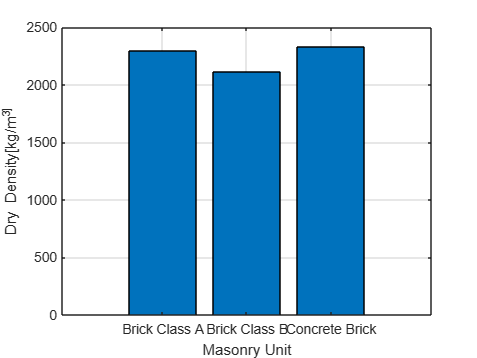

% Define the data
x = {'Brick Class A', 'Brick Class B', 'Concrete Brick'};
y = [2292.85, 2111.11, 2330.76];

% Create the  first bar plot
bar(y);

% Customize the bar plot

xlabel('Masonry Unit'); % X-axis label of the plot
ylabel('Dry Density[kg/m^3]'); % Y-axis label of the plot
xticks(1:numel(x)); % Set X-axis ticks
xticklabels(x); % Set X-axis tick labels

% Display the bar plot
grid on;

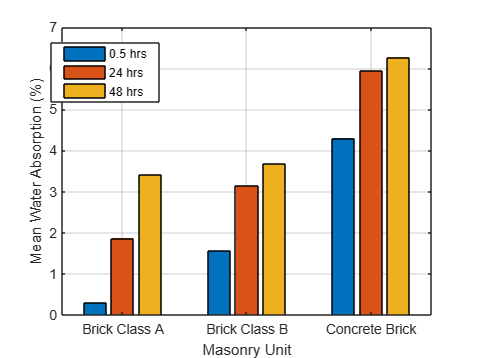




% Data for the  second bar plot
x = {'Brick Class A', 'Brick Class B', 'Concrete Brick'};
hrs = [0.5, 24, 48];
data = [
    0.31, 1.87, 3.42;
    1.57, 3.15, 3.68;
    4.3, 5.94, 6.27
];

% Create the second bar plot
bar(data);

% Customize the plot
title(''); % Remove the title of the of the plot
xlabel('Masonry Unit'); % X-axis label of the plot
ylabel('Mean Water Absorption (%)'); % Y-axis label of the plot
set(gca,'xtick',1:numel(x),'xticklabel',x); % Set x-axis ticks and labels of the plot


% Create a legend for the different time intervals in the plot
legend(arrayfun(@(x) sprintf('%g hrs', x), hrs, 'UniformOutput', false), 'Location', 'Best');

% Remove the legend title
legend('off');

% Remove chart title
title('');

% Display the plot
grid on;

xlim([0.51 3.49])
ylim([0.00 7.00])
legend("Position", [0.12736,0.72944,0.1892,0.13966])

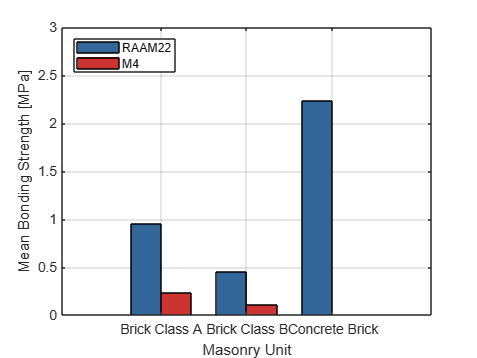


% Data for Table 3
Masonry_Unit_3 = {'Brick Class A', 'Brick Class B', 'Concrete Brick'};
Bonding_Strength_3 = [0.95, 0.45, 2.23];

% Data for Table 4
Masonry_Unit_4 = {'Brick Class A', 'Brick Class B', 'Concrete Brick'};
Bonding_Strength_4 = [0.23, 0.11, NaN];

% Create the third plot
figure;

% Width of each bar group
barWidth = 0.35;

% Calculate the x-positions for bars of the plot
x1 = 1:numel(Masonry_Unit_3);
x2 = x1 + barWidth;

% Create the first set of bars for Table 3 with custom colors
bar_1 = bar(x1, Bonding_Strength_3, barWidth, 'FaceColor', [0.2 0.4 0.6]); % Blue color for Table 3 bars

hold on; % Hold the plot to add the second set of bars

% Create the second set of bars for Table 4 with custom colors
bar_2 = bar(x2, Bonding_Strength_4, barWidth, 'FaceColor', [0.8 0.2 0.2]); % Red color for Table 4 bars

hold off; % Release the hold

% Customize the plot
title(''); % Remove the title
xlabel('Masonry Unit');
ylabel('Mean Bonding Strength [MPa]'); % Y-axis label 
set(gca,'xtick',x1 + barWidth / 2,'xticklabel',Masonry_Unit_3); % Set x-axis ticks and labels


% Create a legend with table names and different colors
legend({'RAAM22', 'M4'}, 'Location', 'Best');

% Display the plot
grid on;

xlim([0.02 4.33])
ylim([0.00 3.00])
legend("Position", [0.15503,0.79873,0.21436,0.096369])